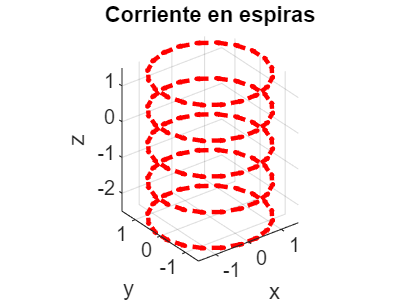

clc;
clearvars;
close all;

N = 20;
s = 1;
ne = 5;
dtheta = (2*pi)/N;
angulo = 0:dtheta:(2*pi - dtheta);
radio = 1.5;
h = 1;
I = 300;
mo = 4*pi*1e-7;
km = mo * I / (4*pi);
rw = 0.2;

for i = 1:ne
    x(s:s + N - 1) = radio * cos(angulo);
    y(s:s + N - 1) = radio * sin(angulo);
    z(s:s + N - 1) = -ne/2 * h + (i - 1) * h;
    dx(s:s + N - 1) = -y(s:s + N - 1) * dtheta;
    dy(s:s + N - 1) =  x(s:s + N - 1) * dtheta;
    s = s + N;
end

dz = zeros(1, N * ne);


figure(1);
quiver3(x, y, z, dx, dy, dz, 0.5, 'r', 'LineWidth', 2);
title('Corriente en espiras');
xlabel('x'); ylabel('y'); zlabel('z');
axis equal;
grid on;


% Campo magnético
xcampo = -5:0.1:5; ycampo = xcampo; zcampo = xcampo;

lx = length(xcampo);
ly = length(ycampo);
lz = length(zcampo);

Bx = zeros(lx, ly, lz);
By = zeros(lx, ly, lz);
Bz = zeros(lx, ly, lz);

tic
for i = 1:lx
    for j = 1:ly
        for k = 1:lz
            for l = 1:ne*N
                rx = xcampo(i) - x(l);
                ry = ycampo(j) - y(l);
                rz = zcampo(k) - z(l);

                r = sqrt(rx^2 + ry^2 + rz^2 + rw^2);
                r3 = r^3;

                Bx(i, j, k) = Bx(i, j, k) + km * (dy(l) * rz - dz(l) * ry) / r3;
                By(i, j, k) = By(i, j, k) + km * (dz(l) * rx - dx(l) * rz) / r3;
                Bz(i, j, k) = Bz(i, j, k) + km * (dx(l) * ry - dy(l) * rx) / r3; 
            end
        end
    end
end
toc

Elapsed time is 14.262408 seconds.


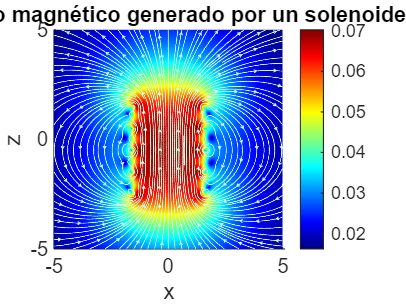


% Graficar plano XZ
Bmag = sqrt(Bx.^2 + By.^2 + Bz.^2);
centery = round(ly / 2);
Bx_xz = squeeze(Bx(:, centery, :));
Bz_xz = squeeze(Bz(:, centery, :));
Bxz = squeeze(Bmag(:, centery, :));

figure(2);
hold on;
pcolor(xcampo, zcampo, (Bxz').^(1/3)); shading interp; colormap jet; colorbar;
h1 = streamslice(xcampo, zcampo, Bx_xz', Bz_xz', 3);
set(h1, 'Color', [0.8 1.0 0.9]);

xlabel('x'); 
ylabel('z');
title('Campo magnético generado por un solenoide');